This script read DLC classification data, train a model to classify these results, and apply it to other dataset

% Load and gather training data
cd E:\DLSOpt\Data\ANMs\Claire\Sessions
Rootfolder = pwd;

CuratedSessions = {
    '20220117'
    '20220118'
    '20220119'
    '20220120'
%     '20220121'
    };

UncuratedSessions = {
    '20220123'
    '20220124'
    };

Features           =       []; 
Responses          =       [];
 

d = table();

for i =1:length(CuratedSessions)

    FindSpeedDLCTable = dir(fullfile(Rootfolder, CuratedSessions{i}, ['TrajDLC*' CuratedSessions{i} '.csv']));
    SpeedTable =fullfile(FindSpeedDLCTable.folder,FindSpeedDLCTable.name);
    iTable = readtable(SpeedTable);

    iTable.Session = repmat(CuratedSessions{i}, size(iTable, 1), 1);
    d = [d; iTable];

end;

writetable(d, 'DLCTrajTrainingData.csv')



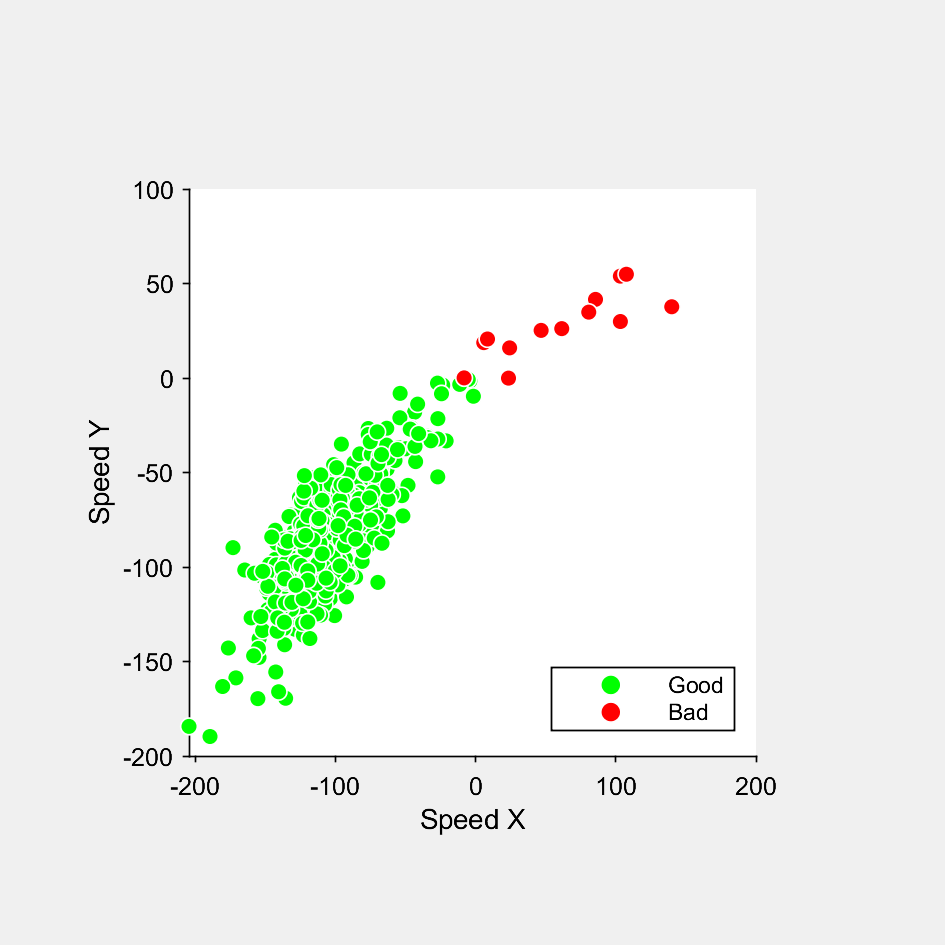

traj_table = readtable(fullfile(Rootfolder, 'DLCTrajTrainingData.csv'));

% construct training data:

feature_names = {};
X = [];
Y = [];
% read feature names
for k = 1:length(traj_table.Properties.VariableNames)

    k_feature = traj_table.Properties.VariableNames{k};
    if contains(k_feature, 'TrajX_') || contains(k_feature, 'TrajY_') || contains(k_feature, 'TrajXMed') || contains(k_feature, 'TrajYMed')
        feature_names = [feature_names {k_feature}];
        X = [X traj_table.(k_feature)];
    end;

    if contains(k_feature, 'isGood')
        Y = traj_table.('isGood');
    end; 
end;

Nsample = size(X, 1);

 
% Plot the data

figure(12);clf(12)
set(12, 'units', 'centimeters', 'position', [5 5 10 10],'Visible','On');
ha = axes('units', 'centimeters', 'position', [2 2 6 6], 'nextplot', 'add');

% plot

hs(1) = scatter(X(Y==1, strcmp(feature_names, 'TrajXMed')), X(Y==1, strcmp(feature_names, 'TrajYMed')), 25, 'g', 'filled', 'MarkerEdgeColor','w');
hs(2) = scatter(X(Y==0, strcmp(feature_names, 'TrajXMed')), X(Y==0, strcmp(feature_names, 'TrajYMed')), 25, 'r', 'filled', 'MarkerEdgeColor','w');
legend('Good', 'Bad','Location','SouthEast')
xlabel('Speed X')
ylabel('Speed Y')

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |    0.021654 |     0.11505 |    0.021654 |    0.021654 |     0.004608 |      0.09834 |
|    2 | Best   |    0.003937 |    0.056187 |    0.003937 |   0.0048328 |       900.86 |        201.9 |
|    3 | Accept |    0.021654 |    0.060104 |    0.003937 |   0.0039388 |     0.013026 |       236.16 |
|    4 | Accept |    0.021654 |     0.13249 |    0.003937 |   0.0039388 |       4.9567 |      0.17976 |
|    5 | Accept |    0.003937 |    0.058419 |    0.003937 |   0.0039356 |       368.14 |        220.3 |
|    6 | Accept |    0.003937 |    0.051449 |    0.003937 |   0.

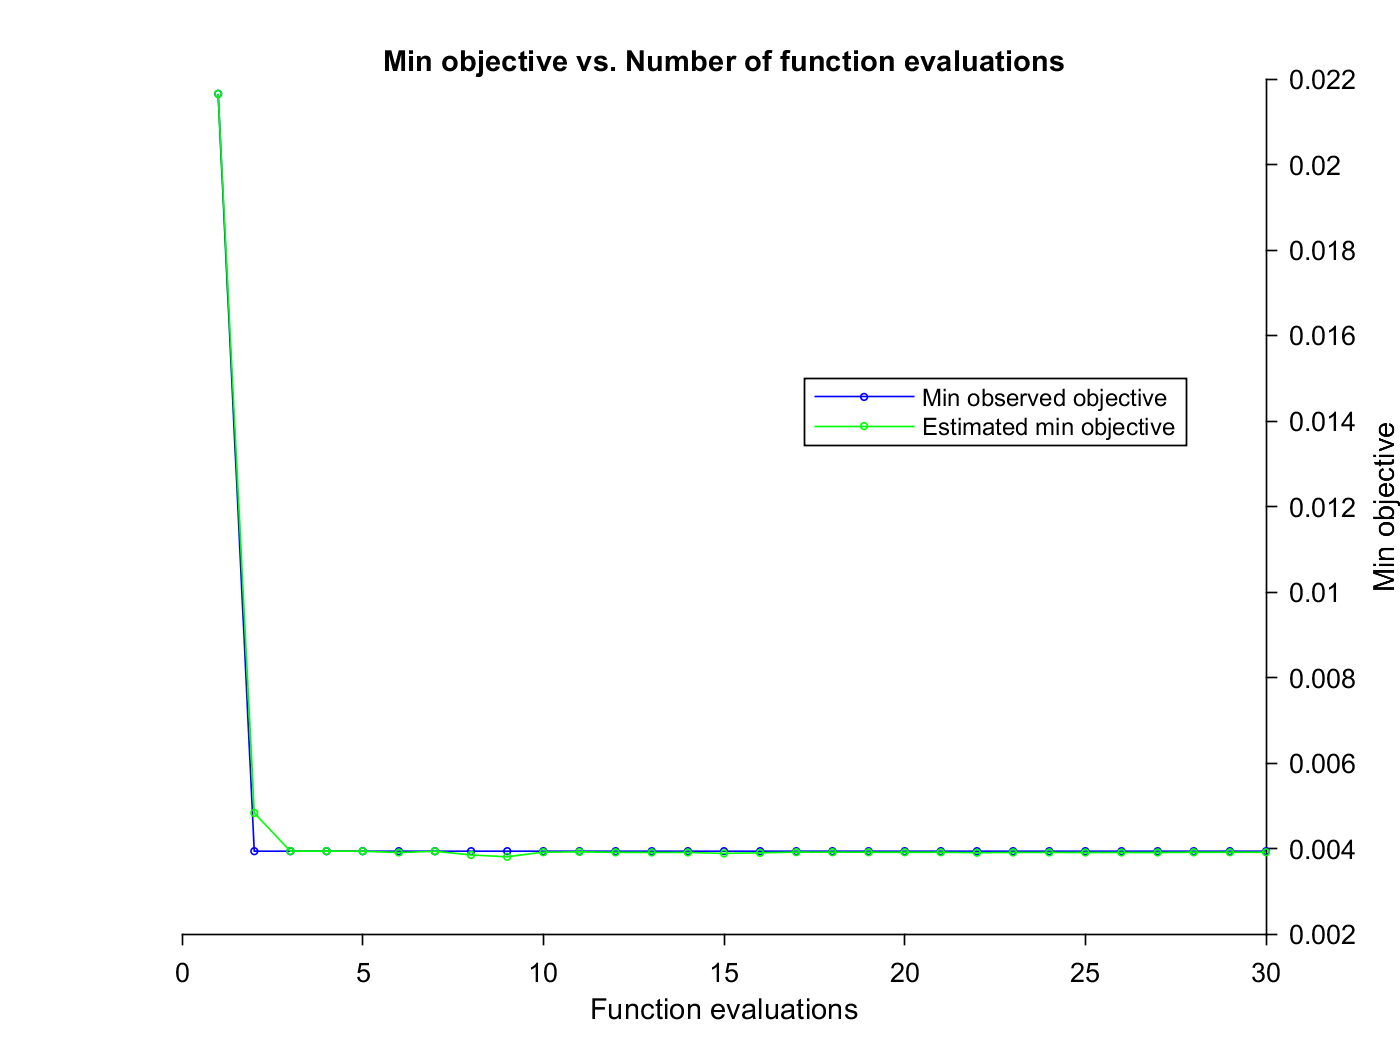

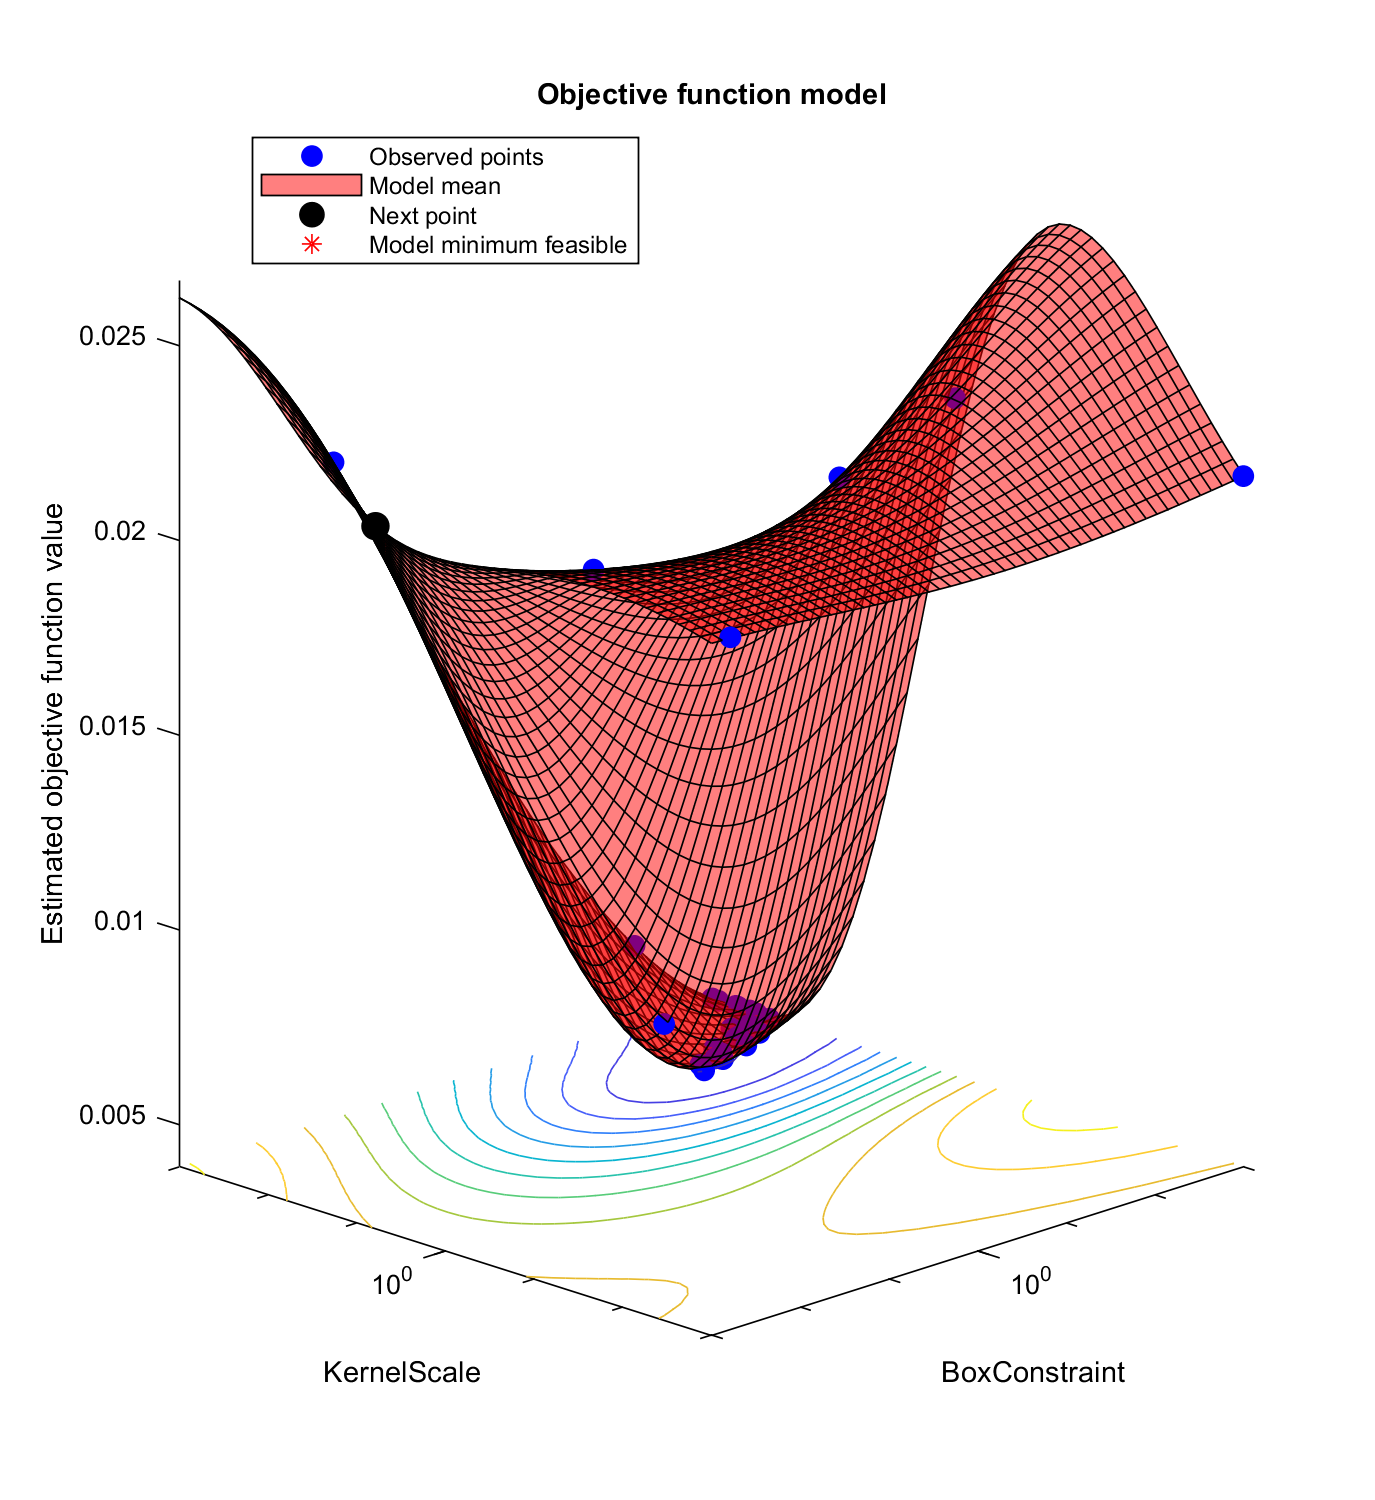


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 26.0853 seconds
Total objective function evaluation time: 2.0228

Best observed feasible point:
    BoxConstraint    KernelScale
    _____________    ___________

       900.86           201.9   

Observed objective function value = 0.003937
Estimated objective function value = 0.0039549
Function evaluation time = 0.056187

Best estimated feasible point (according to models):
    BoxConstraint    KernelScale
    _____________    ___________

       87.275          79.404   

Estimated objective function value = 0.0039119
Estimated function evaluation time = 0.056098



% Train an SVM model to seperate Good and Bad.

% split up train, cross validation, and test
rng(1)
Nsample = size(X, 1);
rand_num = randperm(Nsample);
ratio = 0.9;
% 80% for model training, 20% for cross validation
X_train = X(rand_num(1:round(ratio*Nsample)), :);
Y_train = Y(rand_num(1:round(ratio*Nsample)));
X_test  = X(rand_num(round(ratio*Nsample)+1:Nsample), :);
Y_test  = Y(rand_num(round(ratio*Nsample)+1:Nsample));

% cross validation samples
cv =cvpartition(Y_train, 'KFold', 5);

% feature selection
opts = statset('display', 'iter');

thisf = @(train_data, train_labels, test_data, test_labels)...
        sum(predict(fitcsvm(train_data, train_labels, 'KernelFunction', 'linear'), test_data)~=test_labels);

% create an inline function which will perform SVM on each column
% classf = @(train_data, train_labels, test_data, test_labels)...
%     sum(predict(fitcsvm(train_data, train_labels, 'KernelFunction','rbf'), test_data)~=test_labels);

% fs will hold the most appropriate features
% [fs, history] = sequentialfs(thisf, X_train, Y_train, 'cv', cv, 'options', opts, 'direction', 'backward', 'nfeatures',2);

 X_train = X_train(:, [15 16]);
 X_test  = X_test(:, [15 16]);

% predict, using linear, gaussian, rbf (Gaussian kernel)
mdl = fitcsvm(X_train, Y_train, 'KernelFunction', 'gaussian', ...
    'OptimizeHyperparameters','auto', ...
    'HyperparameterOptimizationOptions', struct('AcquisitionFunctionName', 'expected-improvement-plus','ShowPlots', true));


[pred,score] = predict(mdl, X_test);

accuracy = (mean(double(pred == Y_test))*100);
disp(accuracy)

   100



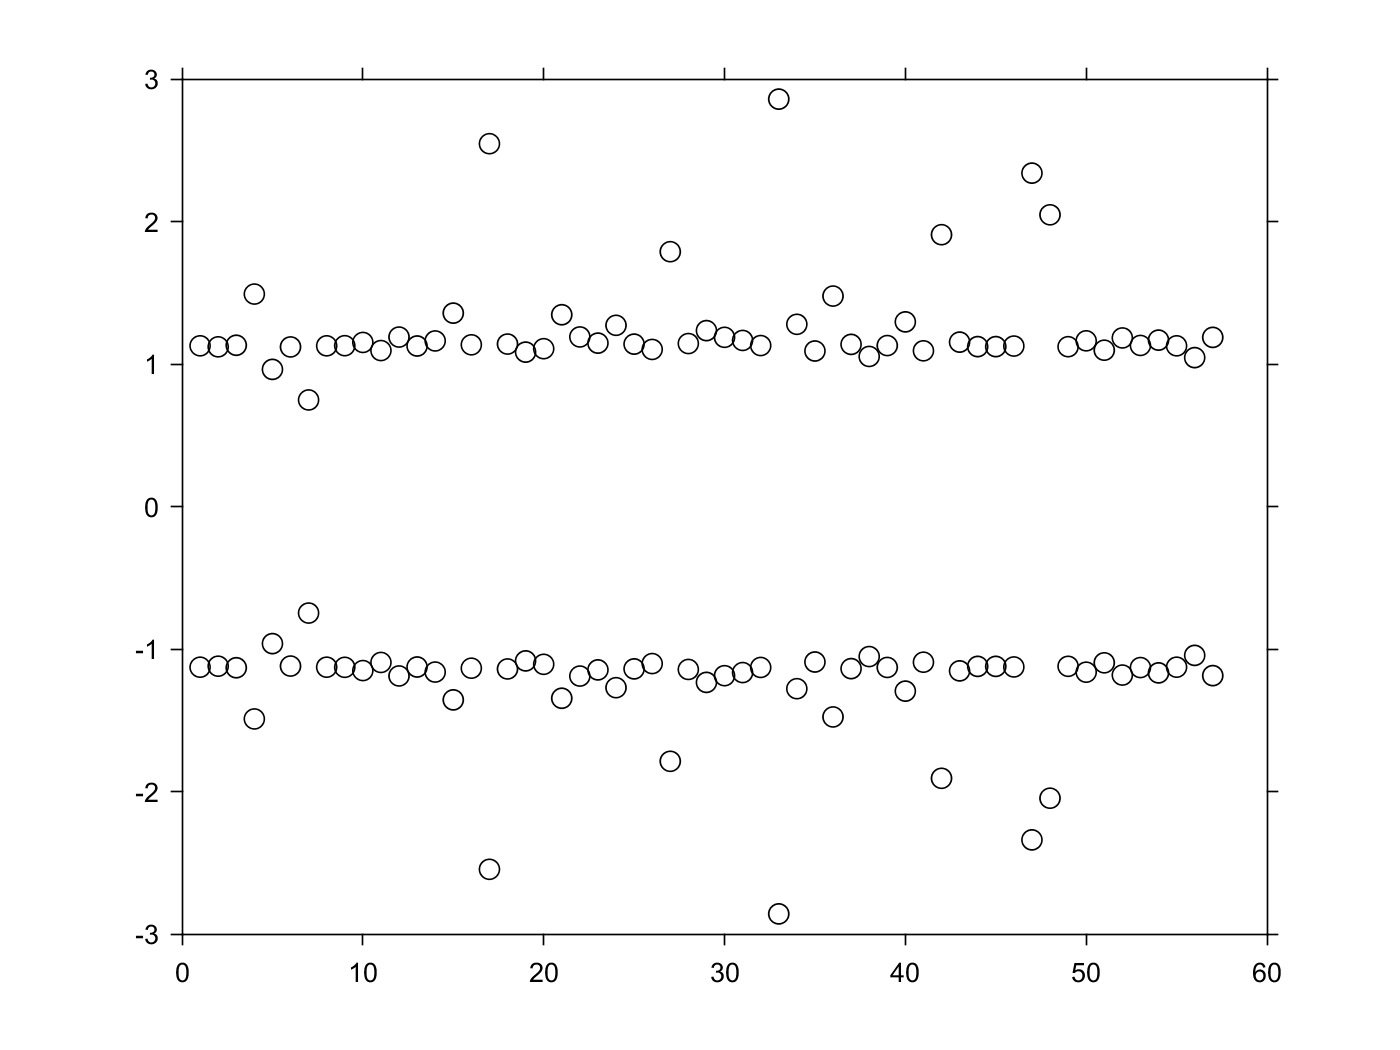



figure;
plot(score, 'ko')


% Estimate Posterior probability
mdl = fitPosterior(mdl);

save SVMModel mdl


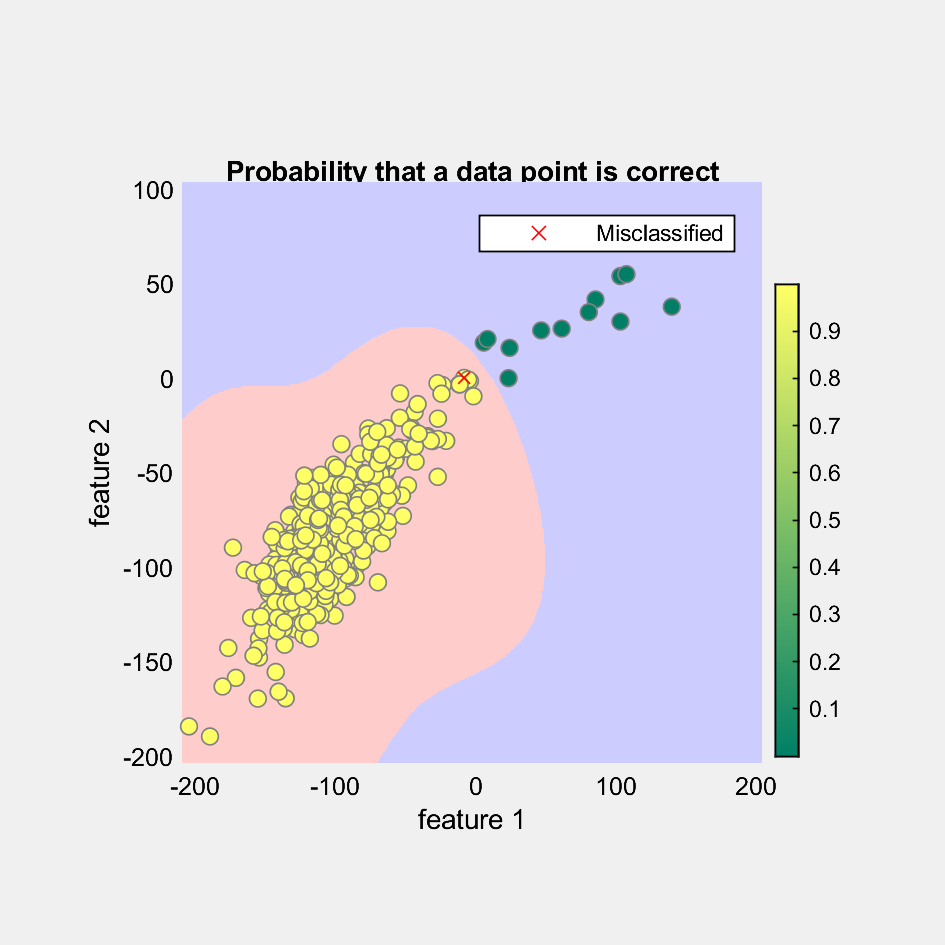

% Show hyperplane

figure(15);clf(15)
set(15, 'units', 'centimeters', 'position', [5 5 10 10],'Visible','On');
ha = axes('units', 'centimeters', 'position', [2 2 6 6], 'nextplot', 'add');
% plot
[Y_predict, score] = predict(mdl, X(:, [15 16]));

% plot the probability 
hs = scatter(X(:, 15), X(:, 16), 25, score(:, 2), 'filled', 'markeredgecolor', [0.5 0.5 0.5]);

hc = colorbar('units', 'centimeters', 'position', [8.2 2 0.25 5]);
colormap(summer)

% plot those that are misclassified

MisClass = Y_predict ~= Y;
hmiss = scatter(X(MisClass, 15), X(MisClass, 16), 25, 'r', 'x');

title('Probability that a data point is correct')
xlabel('feature 1')
ylabel('feature 2')

% hs(1) = scatter(X_train(Y_train==1, 1), X_train(Y_train==1, 2), 25, 'g', 'filled', 'MarkerEdgeColor','w');
% hs(2) = scatter(X_train(Y_train==0, 1), X(Y_train==0, 2), 25, 'r', 'filled', 'MarkerEdgeColor','w');
% legend('Good', 'Bad','Location','SouthEast')
% xlabel('Traj X')
% ylabel('Traj Y')

% plot model
% h_sv = plot(mdl.SupportVectors(:, 1), mdl.SupportVectors(:, 2), 'ko', 'markersize',8);

% plot decision plane
Xlim = get(gca, 'xlim');
Ylim = get(gca, 'ylim');

[xi,yi] = meshgrid([Xlim(1):1:Xlim(2)],[Ylim(1):1:Ylim(2)]);
dd = [xi(:), yi(:)];
pred_mesh = predict(mdl, dd);
redcolor = [1, 0.8, 0.8];
bluecolor = [0.8, 0.8, 1];
pos = find(pred_mesh == 1);
h1 = plot(dd(pos,1), dd(pos,2),'s','color',redcolor,'Markersize',5,'MarkerEdgeColor',redcolor,'MarkerFaceColor',redcolor);

pos = find(pred_mesh == 0);
h2 = plot(dd(pos,1), dd(pos,2),'s','color',bluecolor,'Markersize',5,'MarkerEdgeColor',bluecolor,'MarkerFaceColor',bluecolor);
set(gca, 'xlim', Xlim, 'ylim', Ylim)
uistack(h1,'bottom');
uistack(h2,'bottom');

legend([hmiss], {'Misclassified'})